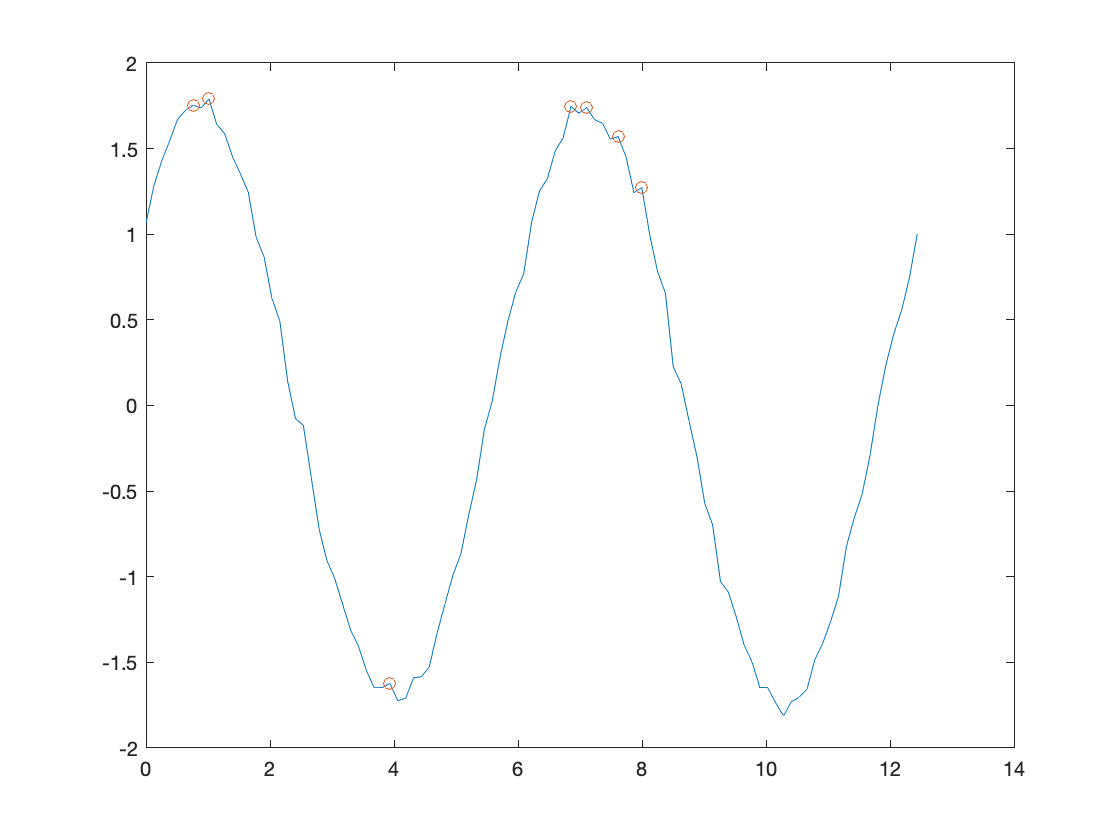

clc;
clear;

x = linspace(0, 2 * pi) * 2;
x = x(1:(end-1));
y = (1+rand(1)) * sin(x+rand(1)) + randn(size(x)) * 0.05;

% Generate difference between each value
ddy = [0 diff(sign(diff(y))) 0];
ind = (ddy == -2);

plot(x, y, x(ind), y(ind), 'o');